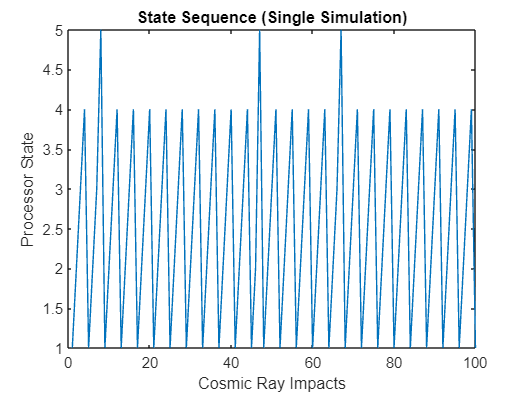

% Define number of states and error probabilities
num_states = 5;
error_prob = [0.01 0.05 0.08 0.02 0.005];

% Initial state
initial_state = 1;

% Simulation parameters
num_simulations = 1000; % Number of simulations to run
max_impacts = 100; % Maximum number of cosmic ray impacts per simulation

% Initialize variables
all_state_sequences = zeros(num_simulations, max_impacts);
error_counts = zeros(num_simulations, 1);
time_to_error = ones(num_simulations, 1);
avg_error_rate_s = zeros(num_simulations, 1);

% Loop for multiple simulations
for sim_idx = 1:num_simulations
  %error_prob = poisspdf(0:num_states-1, rand*5);
  % Current state
  current_state = initial_state;
  
  % Loop for impacts within a single simulation
  for impact_idx = 1:max_impacts
    % Check for cosmic ray impact
    if rand < error_prob(current_state)
      % Transition to an error state
      %new_state = randi(num_states - 1, 1) + 1;
      % while new_state == current_state
      %   new_state = 1;
      % end
      current_state = num_states;
    end
    
    % Record state in the sequence
    all_state_sequences(sim_idx, impact_idx) = current_state;
    
    % Transition to next state
    if current_state == 5   % If current_state is an error state
        if rand < error_prob(current_state) % calculate  if it remains in error
            current_state = 5;
        else    % Else go to the first state
            current_state = 1;
        end
    else
        current_state = current_state+1;
        if current_state == 5   % Dont go to error state, when there is no error
            current_state = 1;  % Go to the first state instead
        end
    end
  end
  
  % Analyze errors for this simulation
  error_counts(sim_idx) = sum(all_state_sequences(sim_idx,:) > 4); % Assuming states 3-5 are error states
  if any(all_state_sequences(sim_idx,:) > 4) % Check if any element is greater than 2
    time_to_error(sim_idx) = find(all_state_sequences(sim_idx,:) > 4, 1, 'first');
  end
  
  avg_error_rate_s(sim_idx) = mean(error_counts(sim_idx)) / max_impacts;

end

% Average error rate
avg_error_rate = mean(error_counts) / max_impacts;

% Average time to error
avg_time_to_error = mean(time_to_error(time_to_error ~= max_impacts)); % Exclude simulations without errors

% Plot state transitions for a single simulation (optional)
figure;
plot(1:max_impacts, all_state_sequences(1,:));
xlabel('Cosmic Ray Impacts');
ylabel('Processor State');
title('State Sequence (Single Simulation)');

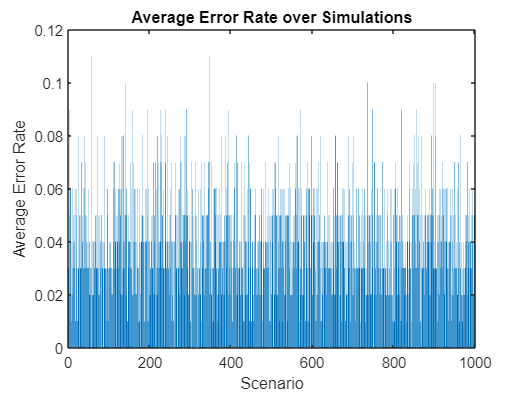


% Plot average error rate
figure;
bar(1:sim_idx, avg_error_rate_s);
xlabel('Scenario');
ylabel('Average Error Rate');
title('Average Error Rate over Simulations');

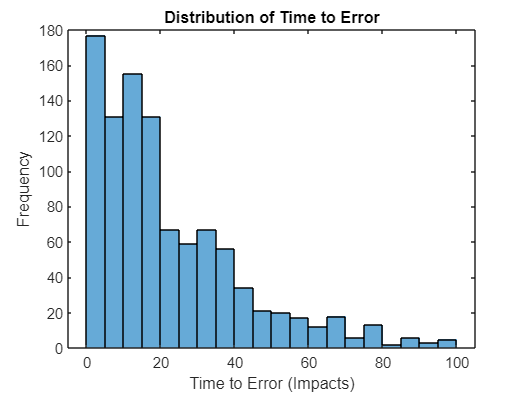


% Plot distribution of time to error (optional)
figure;
histogram(time_to_error(time_to_error ~= max_impacts));
xlabel('Time to Error (Impacts)');
ylabel('Frequency');
title('Distribution of Time to Error');


% Display results
disp(['Average Error Rate: ' num2str(avg_error_rate)]);

Average Error Rate: 0.04046


disp(['Average Time to Error: ' num2str(avg_time_to_error)]);

Average Time to Error: 21.887
